# Quickstart Guide: Solver

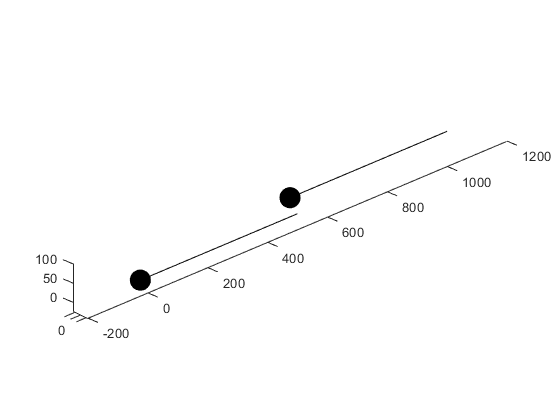

soma = ELFENN.Section('soma', 'radius', 25,...
    'sectionLength', 50, 'nSeg', 1, 'sectionGeometry', 'S');
axon = ELFENN.Section('axon', 'radius', 2.5, ...
    'sectionLength', 500, 'nSeg', 5);

cell = ELFENN.Cell('cell1');
cell.connectsection(soma, axon, [0,0,0]); 

network = ELFENN.Network();
network.addcell(cell, [0,0,0]);
cell.name = 'cell2';
network.addcell(cell, [500,0, 50]);
network.complete();
network.setdynamics(ELFENN.Mechanisms.Cellular.HH.default_parameters())

plotnetwork(network, 'style', 'line')
view([-45. 25])

We are going to add a dc current into the soma of cell1 and add a synapse between the end of cell1 and the soma of cell2.

We add the synapses as before

endix = network.cells(1).sections(2).segments(end).connectivityid;
synapse_params = ELFENN.Mechanisms.Synapse.Alpha.default_parameters;
synapse_params.tau = 0.1;
synapse_params.gSyn = 2; % uS

network.addchemicalsynapse(network.getcellbyname('cell2').soma,...
    endix, @ELFENN.Mechanisms.Synapse.Alpha.s, ...
    synapse_params, 'unscaled');

similarly the current injection

injectedParameters.amp = 1; % nA
network.addintracellularelectrode(network.getcellbyname('cell1').soma,...
    @ELFENN.Mechanisms.Stimulus.dc_stimulus, injectedParameters, 'unscaled')

As menitoned previously here we add the dynamics to the model with the supervisor. Along  with the conductivity, initial conditions, and the network, the supervisor gives us the solver needed to solve the system.

IC = [-64.974597972708651 0.053091060286233, ...
    0.594063768482307 0.318032413734906];
conductivity = 0.05;
solver = ELFENN.Supervisor(@ELFENN.Mechanisms.Cellular.HH.ode,...
    network, IC, conductivity);

The solver has some important settings like the tolorances, timespan, ephaptic status (ephaptic effects on or off). Possibly most importantly is the "transient" setting.

Often in neuron models there is a very large, very short transient in the first few ms of a simulation, especially with injected currents. Normally these arent too bad, however when ephaptic effects are in play these large transients can be vey hard to solve. As such we have an optional transient where the first optional amount of time is solved with ephaptic coupling turned off. Those solutions are rejected and used as the initial conditions for actual solver.

Here the transients are small so they're the transient skip is not needed however in large simulations (more compartments) and larger currents this can be a manditory step - otherwise the solver may never get past the first time step.

figure();
solver.ephapticStatus = 'on';
solver.transientLength = 0;
solver.tmax = 100;
[t,y] = solver.run();

Just to show the simulation worked we'll plot the membrane potential here, for more detail see the following section.

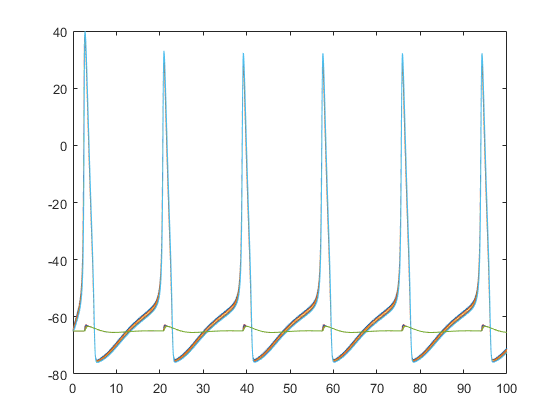

plot(t, y(:, 2:5:end));

## Accessing Solutions

ELFENN solutions are stored in an NxM matrix with each row being a time step and each column being a variable.

For simplicity ELFENN allows us to map segments and variables onto their correct column by naming the variables

network.assignsolutionindex("Vm","m","h","n")

With this we can now see that each segment has a corresponding set of indeces for their variables

ix = network.getsegmentbyid(network.getcellbyname('cell1').soma).ODEID;
disp(ix);

    Vout: 1
      Vm: 2
       m: 3
       h: 4
       n: 5



Each variable has an index which correspondes to the column in the solution. For example suppose we want the membrane potential for both somas. **Please ignore the warning - this is an issue with the editor used to generate these documents and should not occur in your code**

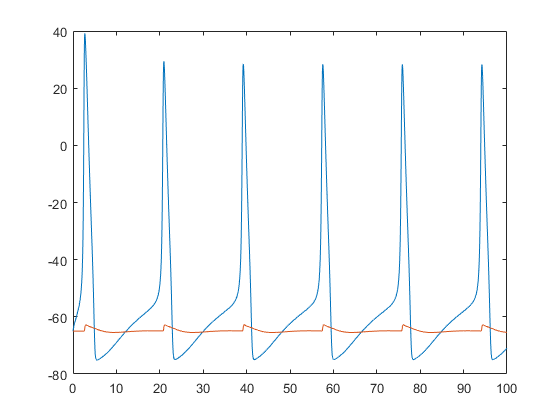

ix1 = network.getsegmentbyid(network.getcellbyname('cell1').soma).ODEID.Vm;
ix2 = network.getsegmentbyid(network.getcellbyname('cell2').soma).ODEID.Vm;
plot(t, y(:, [ix1, ix2]));

We can see the tonic spiking in the first soma and the subthreshold EPSPs in the second soma.